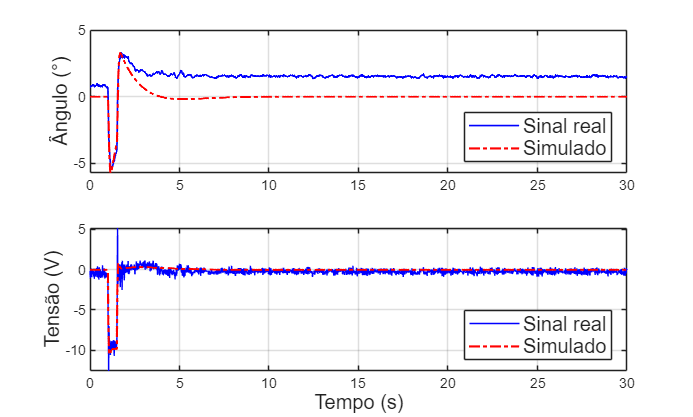

clc;
close all;

% Carregar dados do arquivo
data = load('pulso.txt');

% Definir intervalo de tempo
inicio = 1;
final = 3000;

xInit = 0;
xFinal = 30;


tempo = data(inicio:final, 1)-40;
theta = -data(inicio:final, 2)*57.296; % theta
theta_dot = data(inicio:final, 3)*57.296; % theta_dot
psi = data(inicio:final, 4)*57.296; % X
psi_dot = data(inicio:final, 5)*57.296; % X_dot
entrada = data(inicio:final, 6); % Ação de controle
disturbio = data(inicio:final, 7); % Disturbio

% Dados do Simulink
tempo_sim = out.tout;
theta_sim = out.yout{1}.Values.Data; % theta
theta_dot_sim = out.yout{2}.Values.Data; % theta_dot
psi_sim = out.yout{3}.Values.Data; % omega
psi_dot_sim = out.yout{4}.Values.Data; % omega
entrada_sim = out.yout{5}.Values.Data; % Ação de controle
disturbio_sim = out.yout{6}.Values.Data; % Disturbio

figure;
subplot(2, 1, 1)
plot(tempo, theta-0.3, 'b', 'LineWidth', 1);
hold on;
plot(tempo_sim, theta_sim, '-.r', 'LineWidth', 1.3);
ylabel('Ângulo (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
% ylim([-2.7 1.3]);
hold off;

subplot(2, 1, 2)
plot(tempo, entrada, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, entrada_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Tensão (V)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
% ylim([-11 2.5]);
hold off;

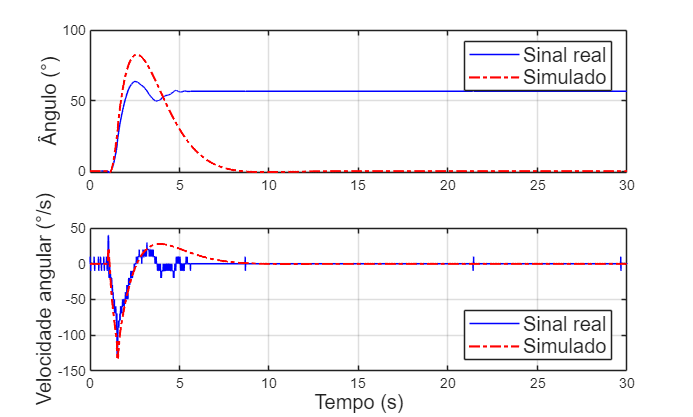


figure;
subplot(2, 1, 1)
plot(tempo, psi-146.791, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, -psi_sim, '-.r', 'LineWidth', 1.3);
ylabel('Ângulo (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
hold off;

subplot(2, 1, 2)
plot(tempo, -psi_dot, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, psi_dot_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Velocidade angular (°/s)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
hold off;

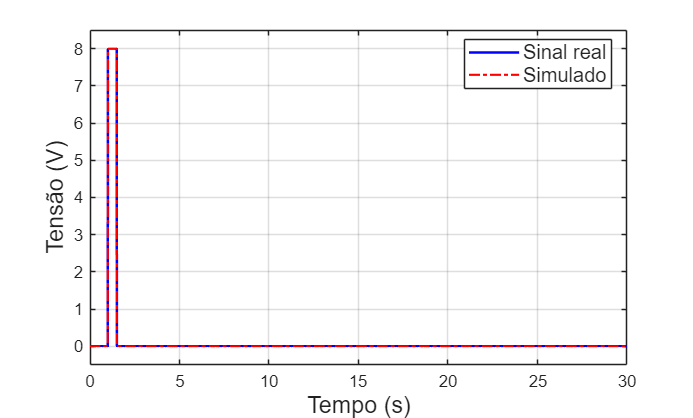


figure;
plot(tempo, disturbio, 'b', 'LineWidth', 1.5);
hold on;
plot(tempo_sim, disturbio_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 14)
ylabel('Tensão (V)', 'FontSize', 14)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([xInit xFinal]);
ylim([-0.5 8.5]);
hold off;